# Eye Model Development

We adopt the Arizona Model as the "paraxial-plus" (due to asphericities) optical foundation of our eye model. Physical distances are always expressed in mm.

#### Source(s) of Truth

- `lensData` (radius of curvature, refractive index, thickness, etc.)

- Iris size and position

#### Derived Value(s)

- Entrance and exit pupil properties (position, magnification, size, etc.)

- Eye centroid

- Anterior Chamber Depth

- Axial length

- Powers and focal lengths

- Retinal magnification factor

Conic surfaces are described by the equation:


$$z = \frac{y^2/R}  {1 +  \sqrt{1 - (K+1) \frac{y^2}{R^2} } }$$


An alternative expression exists for $K \not=-1$:


$$z = \frac{1}{K+1}[R - \sqrt{R^2 - (K+1)y^2} ] $$


Initialize the eye-model in relaxed state and display it a table. 

clearvars
A = 0;  % Diopters of accommodation
model = Arizona(A);
model.data

ans = 6×6 table
     Surface      Radius    Thickness    Index    SemiDiameter    Conic
    __________    ______    _________    _____    ____________    _____

    "OBJ"            Inf       5.00      1.00         5.00         0.00
    "Cornea"        7.80       0.55      1.38         6.00        -0.25
    "Aqueous"       6.50       2.97      1.34         6.00        -0.25
    "Lens"         12.00       3.77      1.42         5.00        -7.52
    "Vitreous"     -5.22      16.71      1.34         5.00        -1.35
    "Retina"      -13.40       0.00      0.00         0.50         0.00


## Eyeball Centroid Estimation

Conic equation written as radial position y as a function of sag is the "upper-half" inverse of standard form:


$$y = \sqrt{ \frac{R^2 - (z(K+1) - R)^2} {K+1}     } $$


Only only upper half is required because we assume a perfectly symmetric eye, expression for the centroid becomes:


$$c = \frac{ \int_{0}^{acd}zc(z)dz + \int_{acd}^{al}zs(z)dz} {\int_{0}^{acd}c(z)dz + \int_{acd}^{al}s(z)dz }$$


We only need to evaluate$\int_{}^{}zc(z)dz$ because characteristic functions $c(z)$ and $s(z)$ only differ in their *K *value. The result is the following integral which we can look up closed-form [solution](https://en.wikipedia.org/wiki/List_of_integrals_of_irrational_functions):


$$\int_{}^{}zc(z)dz = \frac{1}{(K+1)^{5/2}} \int{[u \sqrt{R^2 - u^2}du} + R\sqrt{R^2 - u^2}du]$$


where the following "u-substitution" is used:


$$u=z(K+1)-R \Longrightarrow dz \rightarrow \frac{du}  {K+1}$$


Integral $\int_{}^{}c(z)dz$ is the measure on the set captured by charateristic function $c(z)$, which can be expressed as the following with the same "u-substitution" as above:


$$\int_{}^{}c(z)dz = \frac{1}{(K+1)^{3/2}} \int{\sqrt{R^2-u^2}du}$$


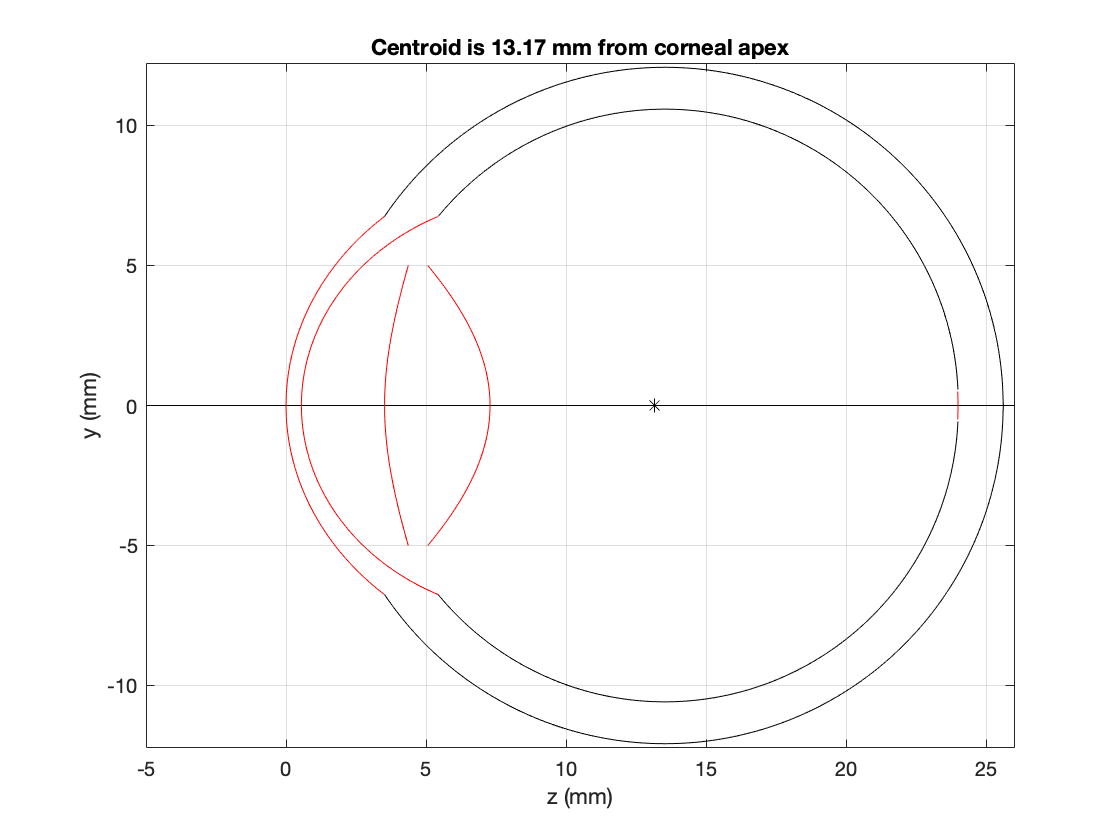

clearvars
model = Arizona();
model.draw(true);
hold on
scatter(model.centroid, 0, 'k*');
title(sprintf("Centroid is %1.2f mm from corneal apex", model.centroid))
hold off

### Verification

Use a pair of ray-transfer matrices for each ocular surface

 
$$M = \pmatrix{1 & 0 \cr \frac{n_1-n_2}{R \cdot n_2 } & \frac{n_1}{n_2} } \pmatrix{1 & d \cr 0 & 1}$$


Input ray parallel to optical axis is modeled as [1; 0]:


$$v_1=Mv_0, v_0= \pmatrix{1 \cr 0}$$


Output from multiplying ray-transfer matrix can be used to compute distance from 2nd principle plane to back-focal plane:


$$H_2F_2=\frac{-1}{tan[v_2(2)]}$$


clearvars
model = Arizona;
model.dioptricPower

ans =          60.69


model.verification;

Pass: Eyeball centroid position (z) agrees with numerical estimate within 0.1 mm, 13.17 mm

model.exitPupil

H2F2 =          22.02


ans =           1.00


Start by tracing ray from OBJ to Retina

%M = arizonaEye.rayMatrix(1,2);
% if T.Thickness < eps, start right at the cornea
model.reverse()

ans = 5×6 table
     Surface      Radius    Thickness    Index    SemiDiameter    Conic
    __________    ______    _________    _____    ____________    _____

    "Vitreous"     13.40      16.71      1.34         0.50         0.00
    "Lens"          5.22       3.77      1.42         5.00        -1.35
    "Aqueous"     -12.00       2.97      1.34         5.00        -7.52
    "Cornea"       -6.50       0.55      1.38         6.00        -0.25
    "OBJ"          -7.80       5.00      1.00         6.00        -0.25






y0 = [1; 0];
T = model.lensData;

Unrecognized method, property, or field 'lensData' for class 'Arizona'.


M = eye(2);
for s = 1:4
    d = T.Thickness(s);
    r = T.Radius(s+1);
    n1 = real(T.Index(s));
    n2 = real(T.Index(s+1));
    M = [1 0; (1/r)*(n1/n2 - 1) n1/n2]*[1 d; 0 1]*M;
end
y =M*y0;
bfl = -y(1) / tan(y(2))
f = -1 / tan(y(2)) / n2;
1000 / f